Getting datastore and labels according to the folder names

fileLocation = uigetdir()

fileLocation = 'C:\Users\Asad PC\Documents\MATLAB\Computer Vision for Engineering and Science\Data\Concrete'

dsConcrete = imageDatastore(fileLocation, "IncludeSubfolders",true, "LabelSource","foldernames");
categories(dsConcrete.Labels)

ans = 2×1 cell array
    {'Negative'}
    {'Positive'}


We can rename the labels accordingly

dsConcrete.Labels = renamecats(dsConcrete.Labels, ["No Crack" "Crack"])

dsConcrete =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\Concrete\Negative\00044.jpg';
                              ' ...\Data\Concrete\Negative\00045.jpg';
                              ' ...\Data\Concrete\Negative\00171.jpg'
                               ... and 997 more
                              }
                     Folders: {
                              ' ...\MATLAB\Computer Vision for Engineering and Science\Data\Concrete'
                              }
                      Labels: [No Crack; No Crack; No Crack ... and 997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage



% spliting into train test sets
[dsTrain, dsTest] = splitEachLabel(dsConcrete, 0.8, "randomized"); 

Extracting features like Mean and standard deviation for all the images in the datatore

intensityAvg = [];
intensitySTD = [];
imgName = [];

while hasdata(dsTrain)
    [img, info] = read(dsTrain);
    
    img = im2double(img);
    img = im2gray(img);
    
    % mean and std functions expects a vector (no 2d matrix) that's why we
    % used img(:) which converts the matrix into single vector
    intensityAvg = [intensityAvg; mean(img(:))];
    intensitySTD = [intensitySTD; std(img(:))];
    
    [~, name, ext] = fileparts(info.Filename);
    imgName = [imgName; string(name) + string(ext)];
end

% Finally create table with all of the outputs  
label = categorical(dsTrain.Labels);
concreteTable = table(label, imgName, intensityAvg, intensitySTD)

concreteTable = 800×4 table
     label        imgName      intensityAvg    intensitySTD
    ________    ___________    ____________    ____________

    No Crack    "00044.jpg"      0.77811         0.023076  
    No Crack    "00171.jpg"      0.82787         0.049307  
    No Crack    "00188.jpg"      0.75051         0.045049  
    No Crack    "00268.jpg"      0.75853          0.05298  
    No Crack    "00272.jpg"      0.78788         0.025274  
    No Crack    "00312.jpg"      0.82332         0.047729  
    No Crack    "00332.jpg"      0.81527         0.027192  
    No Crack    "00422.jpg"      0.77582         0.044448  
    No Crack    "00486.jpg"      0.64485        0.0096845  
    No Crack    "00582.jpg"      0.74048         0.027994  
    No Crack    "00628.jpg"      0.62594           0.0262  
    No Crack    "00697.jpg"      0.59696         0.0203


% Saving the table 
save("concreteIntensityFeatures.mat", "concreteTable", "dsTrain", "dsTest");

Plotting the table to see if we can perform the classification or not?

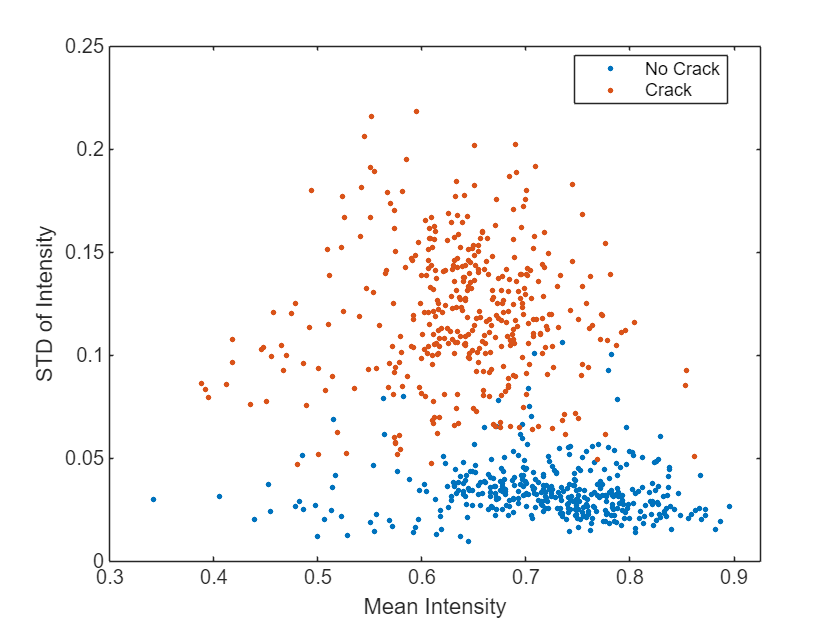

gscatter(concreteTable.intensityAvg, concreteTable.intensitySTD, concreteTable.label)
xlabel("Mean Intensity")
ylabel("STD of Intensity")

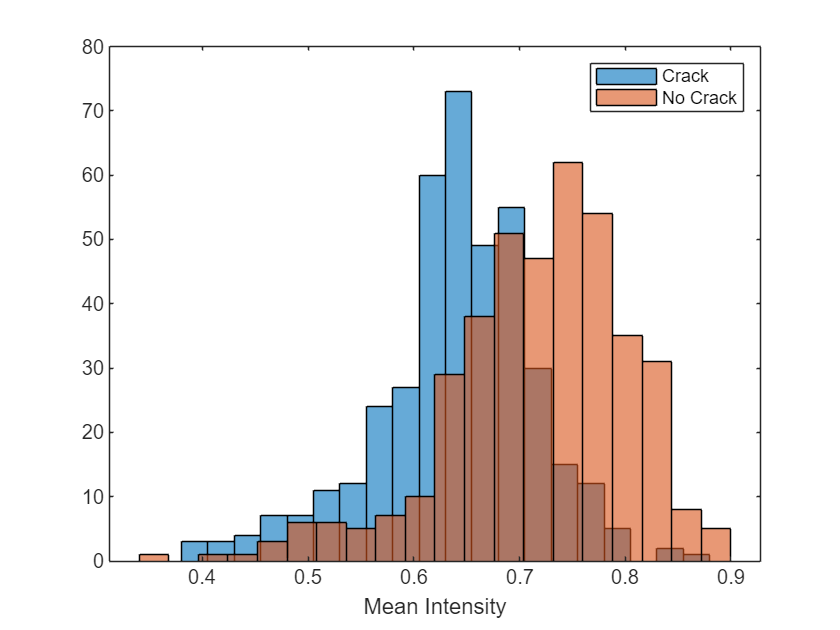

histogram(concreteTable.intensityAvg(concreteTable.label == "Crack"),20)
hold on
histogram(concreteTable.intensityAvg(concreteTable.label == "No Crack"),20)
hold off
xlabel("Mean Intensity")
legend("Crack","No Crack")